## Plot acceleration readings for samples selection

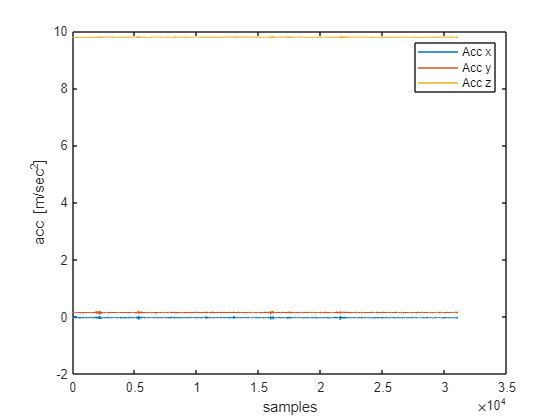

figure
plot(Acceleration.X,'DisplayName','Acc x')
hold on
plot(Acceleration.Y,'DisplayName','Acc y')
plot(Acceleration.Z,'DisplayName','Acc z')
legend
xlabel('samples')
ylabel('acc [m/sec^2]')

## Calculate average acceleration readings

start_ind = 10;
stop_ind = 30900;

z_up_acc_x_mean = mean(Acceleration.X(start_ind:stop_ind));
z_up_acc_y_mean = mean(Acceleration.Y(start_ind:stop_ind));
z_up_acc_z_mean = mean(Acceleration.Z(start_ind:stop_ind));

## Calculate accelerometers parameters

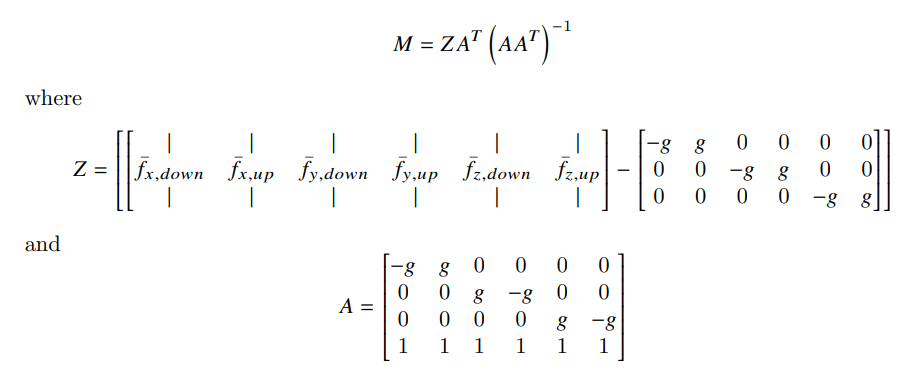

Where:


$$M = [M_A+S_a|b_a]$$


g = 9.79;
f_x_down = [x_down_acc_x_mean; x_down_acc_y_mean; x_down_acc_z_mean];
f_x_up = [x_up_acc_x_mean; x_up_acc_y_mean; x_up_acc_z_mean];
f_y_down = [y_down_acc_x_mean; y_down_acc_y_mean; y_down_acc_z_mean];
f_y_up = [y_up_acc_x_mean; y_up_acc_y_mean; y_up_acc_z_mean];
f_z_down = [z_down_acc_x_mean; z_down_acc_y_mean; z_down_acc_z_mean];
f_z_up = [z_up_acc_x_mean; z_up_acc_y_mean; z_up_acc_z_mean];
z_aux = [-g g 0 0 0 0;...
         0  0 -g g 0 0;...
         0 0 0 0 -g g];
Z = [f_x_down f_x_up f_y_down f_y_up f_z_down f_z_up]-z_aux;
A = [z_aux; 1 1 1 1 1 1];
M = Z*A'/(A*A');


## Gyro parameters calculations

## Calculate average angular velocity readings

start_ind = 200;
stop_ind = 30800;

z_up_gyro_x_mean = mean(AngularVelocity.X(start_ind:stop_ind));
z_up_gyro_y_mean = mean(AngularVelocity.Y(start_ind:stop_ind));
z_up_gyro_z_mean = mean(AngularVelocity.Z(start_ind:stop_ind));

We want to find:

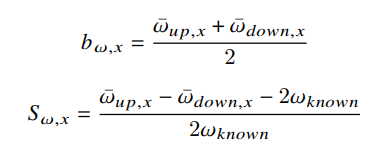

for all three axes considering that earth rotation rate is: $7.29\cdot 10^{-5} \;rad/sec$

omega_earth = 7.29e-5; % rad/sec
% Bias calc
b_omega_x = (x_up_gyro_x_mean+x_down_gyro_x_mean)/2;
b_omega_y = (y_up_gyro_y_mean+y_down_gyro_y_mean)/2;
b_omega_z = (z_up_gyro_z_mean+z_down_gyro_z_mean)/2;
% scale factor calc
S_omega_x = (x_up_gyro_x_mean-x_down_gyro_x_mean-2*omega_earth)/(2*omega_earth);
S_omega_y = (y_up_gyro_y_mean-y_down_gyro_y_mean-2*omega_earth)/(2*omega_earth);
S_omega_z = (z_up_gyro_z_mean-z_down_gyro_z_mean-2*omega_earth)/(2*omega_earth);